**EXERCISE 1**

data = xlsread('SM23_BabyFeatures.xlsx');
features = data(:, 2:end);

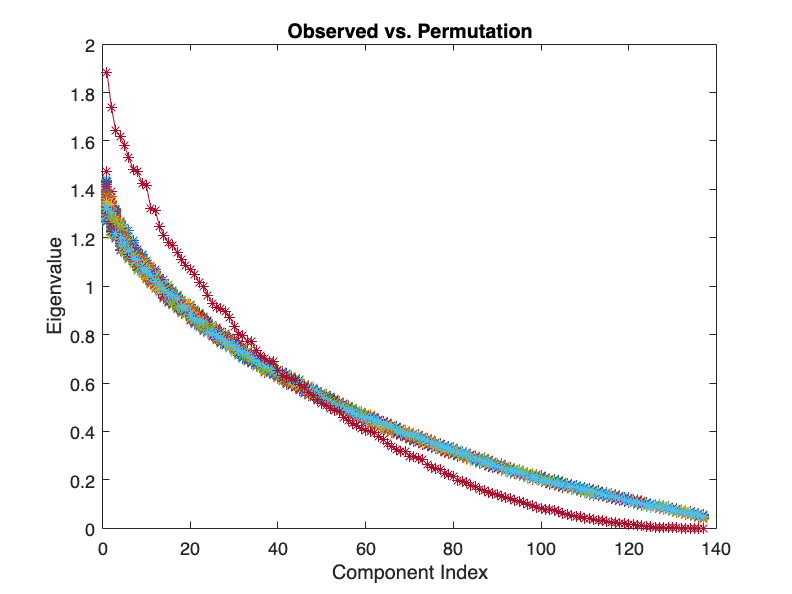

%A)
mean_features = mean(features, 1);
%centered_features = features - mean_features;
cov_matrix = cov(features);

[eigen_vec, eigen_val] = eig(cov_matrix);

[eigen_values, indices] = sort(diag(eigen_val), 'descend');
eigen_vectors = eigen_vec(:, indices);

R = 1000;
replicates = zeros(R, size(eigen_values, 1));
permfeatures = zeros(285, 137);
for i = 1:R
    for j=1:137
        permuted_indices = randperm(size(features, 1))';
        permuted_features = features(:, j);
        permuted = permuted_features(permuted_indices)';
        permfeatures(:,j) = permuted;
    end
    
    permuted_cov_matrix = cov(permfeatures);
    
    [permuted_eigen_vectors, permuted_eigen_values] = eig(permuted_cov_matrix);
    permuted_eigen_values = sort(diag(permuted_eigen_values), 'descend');
    
    replicates(i, :) = permuted_eigen_values';
end

plot(replicates', '*')
hold on;
plot(eigen_values, '-*' )
title('Observed vs. Permutation');
xlabel('Component Index');
ylabel('Eigenvalue');
hold off


alpha = 0.05;
p_values = zeros(1, 137);
%compute the p-value for each column separately
for i=1:137
    n_as_high_as_observed = sum(replicates(:,i) > eigen_values(i)');
    p_values(1,i) = (1+n_as_high_as_observed)/(1+R);
end
p_values;
significant_components = find(p_values < alpha)

significant_components =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    43    44



%B)eigVals=eigen_val(indices,indices);
original_eigen_vectors=eigen_vec(:,indices);

my_size = size(significant_components,2);
sum_var = sum(eigen_values);
principal_component = sum(eigen_values(1:my_size));

percentage = principal_component*100/sum_var 

percentage = 70.7417


selected_eigenvalues = eigen_values(1:my_size);
selected_eigenvectors = eigen_vectors(:, indices(1:my_size));

% Bootstrap resampling
B = 1000; % Number of bootstrap samples
bootstrap_percentages = zeros(B, 1);
samplesize = length(features)

samplesize = 285

for b = 1:B
    bootstrap_indices =  ceil (samplesize*rand(1,samplesize));
    bootstrap_sample = features(bootstrap_indices,:);

    bootstrap_cov_matrix = cov(bootstrap_sample);
    [bootstrap_eigen_vec, bootstrap_eigen_val] = eig(bootstrap_cov_matrix);
 
    [bootstrap_eigen_values, bootstrap_indices] = sort(diag(bootstrap_eigen_val), 'descend');
    bootstrap_eigen_vectors = bootstrap_eigen_vec(:, bootstrap_indices);

    bootstrap_selected_eigenvalues = bootstrap_eigen_values(1:my_size);
    bootstrap_percentage = sum(bootstrap_selected_eigenvalues) * 100 / sum_var;

    bootstrap_percentages(b) = bootstrap_percentage;
end
bootstrap_percentages

bootstrap_percentages =    78.1837
   76.8130
   82.0337
   80.3083
   79.5804
   75.8023
   78.3496
   76.9565
   81.1268
   77.9957




alpha=0.05;
sort_boot = sort(bootstrap_percentages)

sort_boot =    69.1706
   73.1081
   73.1827
   73.2751
   73.3493
   73.6191
   73.7492
   74.2602
   74.2633
   74.4621



t_low = sort_boot(B * alpha/2) 

t_low = 75.0579

t_high= sort_boot(B * (1- (alpha/2)))

t_high = 82.9540


CI_percentiles = [2*percentage - t_high, 2*percentage - t_low]

CI_percentiles =    58.5294   66.4255


%C) Theory question


%D)
alpha = 0.05

alpha = 0.0500

female = data(data(:, 1) == 0, :);
female_features = female(:, 2:end);
female_features = female_features(:, significant_components);

male =  data(data(:, 1) == 1, :);
male_features = male(:, 2:end);
male_features = male_features(:, significant_components);

[n1, p1] = size(female_features);
[n2, p2] = size(male_features);

female_mean = mean(female_features,1);
male_mean = mean(male_features, 1);

female_s = cov(female_features)

female_s =     0.6915    0.0362   -0.0814    0.0438    0.1052   -0.0798   -0.1636    0.0830   -0.0887   -0.0031    0.0811   -0.1426    0.0574    0.0385    0.1489   -0.1969   -0.1146   -0.0201   -0.0309    0.0612   -0.1234   -0.0507   -0.0856    0.0407   -0.0785   -0.0212   -0.0258   -0.0171    0.0398    0.0793    0.0435    0.0798    0.0956    0.0142    0.0484   -0.0417    0.0922   -0.0893    0.0693   -0.0937   -0.0696    0.1234
    0.0362    0.3885    0.0362    0.0650   -0.0416   -0.1201   -0.0184    0.0135   -0.0428   -0.0125   -0.0495   -0.0882   -0.0173   -0.0643    0.0956   -0.0282   -0.0317    0.1274   -0.0615   -0.0737   -0.0482    0.0726   -0.0087    0.0222   -0.0389   -0.0138    0.0331    0.0418   -0.0898    0.0261   -0.0280    0.0688    0.1211    0.0051   -0.0292    0.0196   -0.0296   -0.1010   -0.0223   -0.0160   -0.0819   -0.0696
   -0.0814    0.0362    0.4817    0.0917    0.0195    0.0018    0.0405    0.0803    0.0654   -0.0028   -0.0464    0.0672    0.0967   -0.0931   -0.1

male_s = cov(male_features)

male_s =     0.5982   -0.1034    0.0390    0.0058    0.1073    0.0185    0.0311    0.1035   -0.0963   -0.1322   -0.0249   -0.0223    0.0339   -0.0805   -0.0301   -0.0251   -0.0756    0.0985    0.0528   -0.0197   -0.1064    0.0088   -0.0083    0.0345    0.0986   -0.0455   -0.0300    0.1187   -0.0582   -0.0150   -0.0370    0.0587   -0.0637    0.0610    0.0424    0.0166   -0.0108    0.0034    0.0413   -0.0606   -0.0638    0.0051
   -0.1034    0.4584   -0.0504   -0.0070   -0.0032   -0.0458    0.0640   -0.0267    0.0969    0.0376    0.1181   -0.0522   -0.0784    0.0936   -0.0054    0.0587    0.1068   -0.0037    0.0316    0.0794    0.0486    0.0119    0.0039   -0.0049   -0.0403    0.0377   -0.0755    0.0173   -0.0085    0.0218   -0.0131   -0.0281    0.0161   -0.0581    0.0439   -0.0333   -0.0676   -0.0080    0.0051    0.0316    0.0583    0.0867
    0.0390   -0.0504    0.4468   -0.0051    0.0048    0.0040    0.0090    0.0097   -0.0396   -0.0596   -0.0966   -0.0238    0.0167   -0.0543    0.052


diag_female_s = diag(female_s);
diag_male_s = diag(male_s);

ratio_check = all(diag_female_s ./ diag_male_s >= 1/4 & diag_female_s ./ diag_male_s <= 4);

if ratio_check
    disp('The diagonals are approximately equal (the ratio is between 1/4 and 4).');
else
    disp('The diagonals are not approximately equal.');
end

The diagonals are approximately equal (the ratio is between 1/4 and 4).



%E)

spooled = ((n1-1)/(n1+n2-2))*female_s + ((n2-1)/(n1+n2-2))*male_s;
my_inverse = inv(((1/n1)+(1/n2))*spooled);
t_obs = (female_mean - male_mean)*(my_inverse)*(female_mean-male_mean).'

t_obs = 65.1348

t_crit = (((n1+n2-2)*p1)/(n1+n2-p1-1))*finv(1-alpha, p1,n1+n2-p1-1)

t_crit = 70.4870


if (t_obs>t_crit)
    display('Reject')
else
    display('Fail to reject')
end

Fail to reject



%F)

R = 1000;

size_male = size(male_features,1);
size_female = size(female_features,1);
tBOOT = zeros(1,R);

for b=1: R
    random_indices_male = ceil(size_male*rand(1, size_male));
    random_indices_female = ceil(size_female*rand(1, size_female));

    male_boot =male_features(random_indices_male, :);
    female_boot =female_features(random_indices_female, :);
    
    female_mean = mean(female_boot,1);
    male_mean = mean(male_boot, 1);
    female_cov = cov(female_boot);
    male_cov = cov(male_boot);
    
    spooled_boot = ((n1-1)/(n1+n2-2))*female_cov + ((n2-1)/(n1+n2-2))*male_cov;
    my_inverse_boot = inv(((1/n1)+(1/n2))*spooled_boot);

    tBOOT(b) = (female_mean - male_mean)*my_inverse_boot*(female_mean - male_mean).';
  
end
p_value = (sum(abs(tBOOT(i))>t_crit)+1)/(R+1)

p_value = 0.0020


if p_value < alpha
    display('Reject');
else
    display('Fail to reject')
end

Reject


**EXERCISE 2**

%A)
N = size(features)

N =    285   137



DM = zeros(N(1));

for i= 1 : N(1) -1
    for j =i +1 :N(1)
        DM(i,j) = sqrt(sum(power(features(i,:) - features(j,:),2)));
        DM(j,i) = DM(i,j);
    end
end
DM

DM =          0   12.7029   12.5474   10.2969   12.2141   12.0129   11.0610   11.6560   10.7684   13.4800   11.8779   13.5482   12.0768   12.2173   13.9851   11.3161   12.4518   13.5975    9.5079   10.7117   10.9039   12.1618   12.2514   12.0375   13.4271   12.4351   13.5738   12.7118   12.0088   10.1976   13.1238   12.2883   12.5530   12.7717   13.9893   13.5891   10.5870   12.0813   11.9285   11.4273   12.1299   12.1898   12.4129   12.7692   12.3689   13.1477    9.9606   10.6587   13.2885   13.3306
   12.7029         0   13.0746   12.2816   11.7726   11.8539   11.9422   12.7192   12.5081   13.3365   10.8499   12.8815   11.6678   13.3835   14.2336   12.4241   13.6069   11.7615   11.5056   12.2814   11.9121   11.5980   13.2824   12.0246   13.6878   11.9958   13.6574   14.0408   12.2978    9.3812   13.3617   11.9399   12.2134   12.0804   13.1756   13.9122   11.8794   13.1765   13.4099   12.5442   13.0938   11.6724   11.4133   13.1514   12.6156   13.7347   10.7364   12.7132   12.2181   1


manvir_nia = 2;
carla_nia = 6;

k = manvir_nia + carla_nia + 5;

A = zeros(N(1))

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

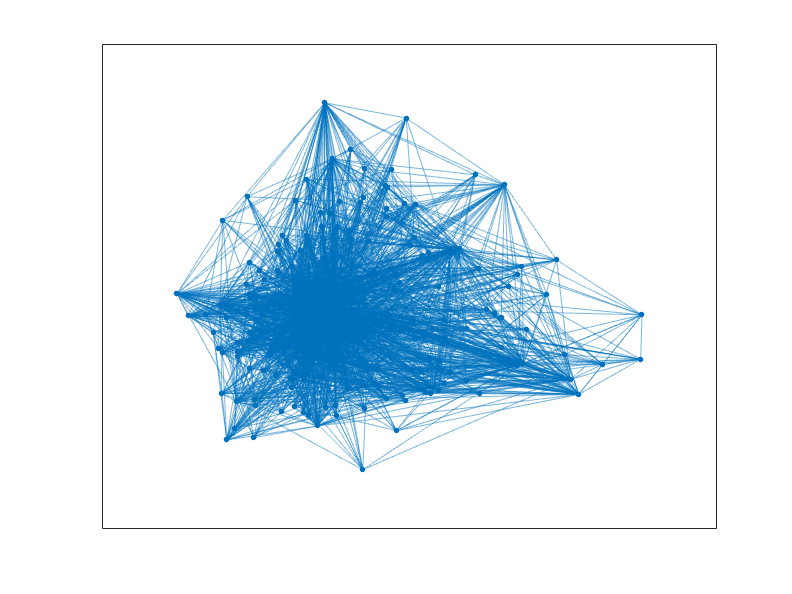

for i =1 : N(1)
    [s_dist, s_idx] = sort(DM(i,:), 'ascend');
    A(i, s_idx(2:k+1)) = 1;
end

% we make the neighbours matrix symetric
AS = (A+A')>0;

for i= 1 : N(1)
    for j =1 :N(1)
        GeoDist(i,j) = AS(i,j) * DM(i,j);
    end
end

mygraph = graph(GeoDist);
plot(mygraph)

GD = distances(mygraph)

GD =          0   19.0879   19.5478   17.2898   18.7811   18.7712   17.4194   18.8288   18.3004   19.9339   18.3345   19.2014   17.7282   18.8578   20.3281   16.8730   19.0806   19.4320   16.8393   18.0568   18.5242   15.4769   19.6081   17.7673   18.9722   18.5072   19.5241   19.5860   18.6084   15.4081   19.8894   18.9213   18.4281   19.3454   20.4013   20.0625   15.7628   19.5526   19.5510   17.7782   18.7784   18.6705   19.0169   18.9799   19.1690   20.2785   11.5781   18.5954   19.6773   19.8513
   19.0879         0   19.0622   20.5842   16.3983   19.2056   15.3331   19.4851   22.1430   18.6914   17.1085   19.4364   18.2849   19.2552   21.3019   17.4297   20.5235   17.3755   16.9824   18.2350   22.2989   18.8207   17.6479   18.0452   19.9214   19.8301   19.6465   19.5395   18.6254    9.3812   19.8285   19.3703   19.0709   19.1523   20.0195   20.3187   17.8967   19.4473   20.5036   18.0728   18.8771   18.0530   19.0678   19.3769   18.9484   19.6880   14.7124   18.7289   20.7931   2



%B)
H = eye(N(1)) - power(N(1),-1)* ones(N(1));

A_mds = (1/2)* GD^2;
B_mds = H * A_mds * H;

[eig_vec,eig_val] = eig(B_mds);
[sort_L, sort_idx] = sort(diag(eig_val),'descend');
U = eig_vec(:, sort_idx);

% Extract the first three ISOMAP dimensions
isomap_dimensions = U(:, 1:3);

variance_retained_isomap = sum(sort_L(1:3)) / sum(diag(eig_val))

variance_retained_isomap = 0.5919


my_size = 3;
sum_var = trace(eig_val);
principal_component = sum(sort_L(1:my_size));

percentage = principal_component/sum_var 

percentage = 0.5919

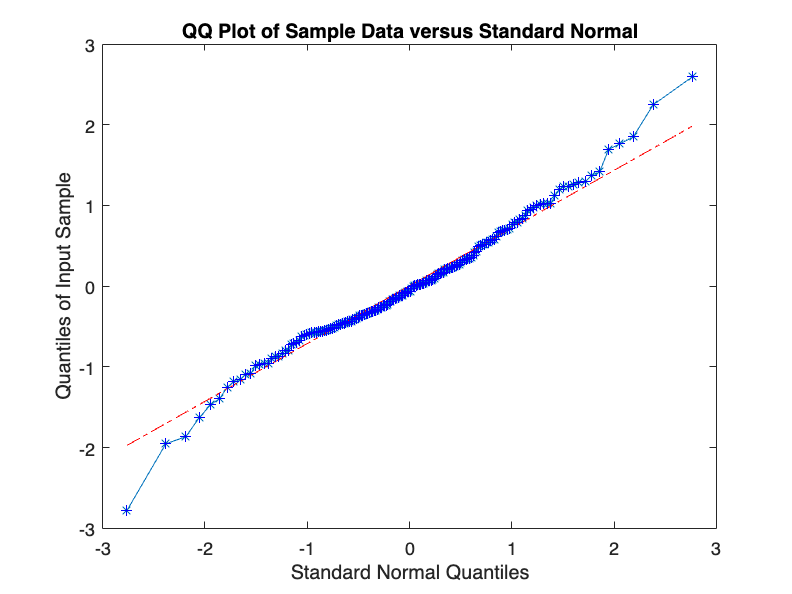



%C)
top_three_features_idx = sort_idx(1:3);
original_data_with_top_features = features(:, top_three_features_idx);
index_male = 1;
index_female = 1;

dataset_male = zeros(174,3);
dataset_female = zeros(111,3);


for i=1:N
    if data(i,1) == 1
        dataset_male(index_male,:) = original_data_with_top_features(i,:);
        index_male = index_male+1;
    end
    if data(i,1) == 0
        dataset_female(index_female, :) = original_data_with_top_features(i,:);
        index_female = index_female+1;
    end

end

dataset_male;
dataset_female;

qtl = norminv(((1:length(dataset_male))-0.5)/length(dataset_male));
myqqplot(dataset_male(:,1));
hold on ;
qqplot(dataset_male(:,1));
hold off;

corr1 = corr(sort(dataset_male(:,1)), qtl')

corr1 = 0.9904


%D)

[n1, p1] = size(dataset_male);
[n2, p2] = size(dataset_female);

mean_male = mean(dataset_male)

mean_male =     0.0031    0.0506    0.0629


mean_fem = mean(dataset_female)

mean_fem =     0.1405   -0.0668    0.0406


cov_male = cov(dataset_male)

cov_male =     0.5982   -0.1034    0.0390
   -0.1034    0.4584   -0.0504
    0.0390   -0.0504    0.4468


cov_female = cov(dataset_female)

cov_female =     0.6915    0.0362   -0.0814
    0.0362    0.3885    0.0362
   -0.0814    0.0362    0.4817


myinverse = inv(cov_female/n2+ cov_male/n1);
obs_t = ((mean_fem - mean_male)*myinverse*(mean_fem - mean_male).')

obs_t = 4.0885

critical_value = chi2inv(1 - alpha, p1)

critical_value = 7.8147

if obs_t > critical_value
    disp('Reject the null hypothesis');
else
    disp('Fail to reject the null hypothesis');
end

Fail to reject the null hypothesis



%Using boostrap
B = 1000;

for b=1: B
    random_indices_male = ceil(size_male*rand(1, size_male));
    random_indices_female = ceil(size_female*rand(1, size_female));

    male_boot =male_features(random_indices_male, :);
    female_boot =female_features(random_indices_female, :);
    
    female_mean = mean(female_boot,1);
    male_mean = mean(male_boot, 1);
    female_cov = cov(female_boot);
    male_cov = cov(male_boot);
    my_inverse_boot = inv(female_cov/n2 + male_cov/n1);
    tBOOT(b) = (female_mean - male_mean)*my_inverse_boot*(female_mean - male_mean).';
  
end
p_value = (sum(tBOOT(i)>critical_value)+1)/(R+1)

p_value = 0.0020


if p_value < alpha
    display('Reject');
else
    display('Fail to reject')
end

Reject


**EXERCISE 3**

% Parameters
gamma = 0.01;  

% Compute the kernel matrix
N = size(features, 1);
K = zeros(N(1), N(1));
for i = 1:N(1)
    for j = 1:N(1)
        K(i, j) = exp(-gamma * norm(features(i, :)' * features(j, :)));
    end
end

K

K =     0.4969    0.4807    0.4571    0.5315    0.4700    0.4872    0.5214    0.4701    0.5053    0.4522    0.5195    0.4554    0.4835    0.4393    0.4059    0.5182    0.4453    0.4302    0.5528    0.5188    0.4839    0.4791    0.4320    0.4776    0.4527    0.4643    0.4383    0.4349    0.4705    0.6548    0.4238    0.4547    0.4612    0.4531    0.4157    0.4232    0.4952    0.4406    0.4425    0.5162    0.4554    0.4943    0.4586    0.4514    0.4582    0.4235    0.6391    0.4898    0.4390    0.4106
    0.4807    0.4643    0.4404    0.5159    0.4535    0.4709    0.5055    0.4536    0.4892    0.4355    0.5036    0.4387    0.4671    0.4225    0.3889    0.5023    0.4285    0.4133    0.5374    0.5029    0.4675    0.4627    0.4151    0.4611    0.4360    0.4477    0.4215    0.4181    0.4540    0.6418    0.4069    0.4380    0.4446    0.4364    0.3988    0.4063    0.4790    0.4238    0.4257    0.5003    0.4388    0.4781    0.4420    0.4347    0.4416    0.4066    0.6256    0.4735    0.4222    0

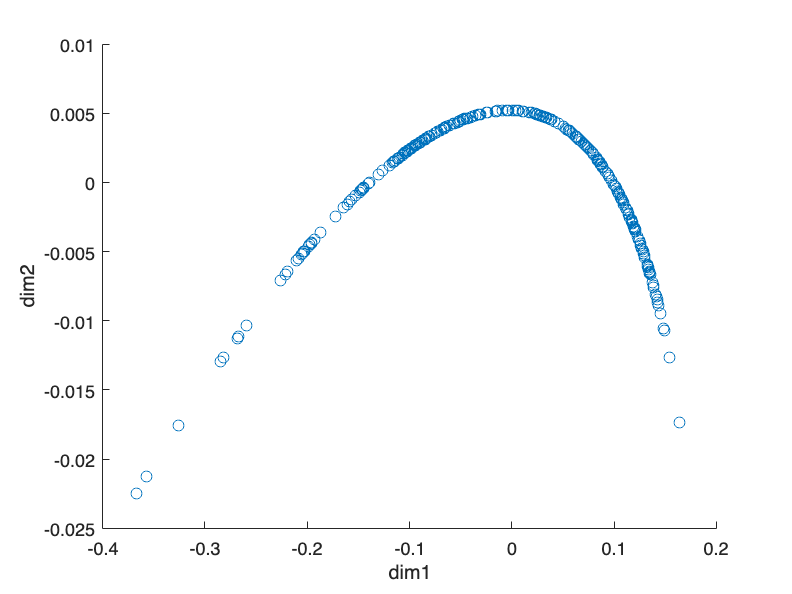

% We compute Kernel PCA: 
H = eye(N(1)) - 1/N(1)*ones(N(1), N(1));
my_matrix = H * K * H;

% We compute the eigenvectors and eigenvalues
my_matrix_cov = cov(my_matrix);
[V, D] = eig(my_matrix_cov);
[eigen_values_sorted, idx_sorted] = sort(diag(D), 'descend');

eigen_vectors_sorted = V(:, idx_sorted);

W = eigen_vectors_sorted(:,1:2);

Y = W' * my_matrix;


scatter(Y(1,:), Y(2,:))
xlabel('dim1');
ylabel('dim2');

%B)

%we only keep one principal component
myeigVals=D(idx_sorted,idx_sorted)

myeigVals =     0.0134         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

myoriginal_eigen_vectors=V(:,idx_sorted)

myoriginal_eigen_vectors =    -0.0276    0.0458   -0.0521   -0.0306   -0.0567    0.0598   -0.0167    0.0074   -0.0048    0.0020    0.0017    0.0371    0.0574    0.0459    0.0341   -0.0079   -0.0034   -0.0290    0.0155    0.0408   -0.0155    0.0043    0.0005    0.0249    0.0500   -0.0252    0.0191    0.0221    0.0071    0.0479   -0.0089    0.0003   -0.1005   -0.0048   -0.0759   -0.0090   -0.0076   -0.0007   -0.0088    0.0184   -0.0294   -0.0187    0.0532   -0.0020   -0.0306   -0.0320    0.0429   -0.0759   -0.0356    0.0889
   -0.0383    0.0292   -0.0593    0.0007   -0.0548    0.0318    0.0050   -0.0318    0.0538    0.0074   -0.0119   -0.0150    0.0085    0.0274   -0.0054   -0.0009    0.0177   -0.0305   -0.0425   -0.0147   -0.0022   -0.0038   -0.0587   -0.0280    0.0087   -0.0335    0.0057    0.0115    0.0022    0.0373   -0.0117   -0.0090    0.0258   -0.0393    0.0719   -0.0006    0.0255    0.0144   -0.0467   -0.1195   -0.0694   -0.0181   -0.0046   -0.0327    0.0280    0.0044   -0.0269  



mysum_var = trace(myeigVals)

mysum_var = 0.0134

myprincipal_component = sum(eigen_values_sorted(1:1))

myprincipal_component = 0.0134


mypercentage = myprincipal_component*100/mysum_var 

mypercentage = 99.8137

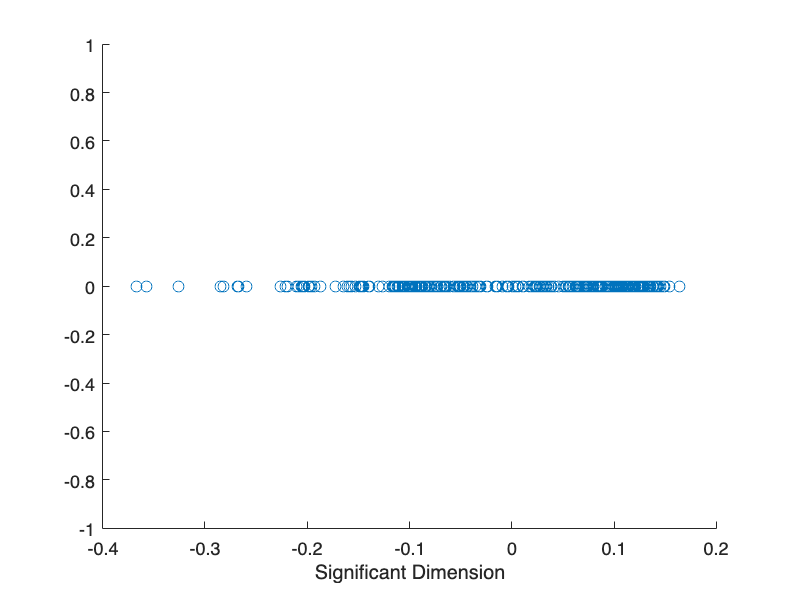

%D)
% Keep only the first significant dimension
Wsel = eigen_vectors_sorted(:, 1);

% Project the data onto the significant dimension
Ysel = Wsel' * my_matrix;

% Scatter plot for visualization
scatter(Ysel, zeros(size(Ysel)));
xlabel('Significant Dimension');


index_male = 1;
index_female = 1;

dataset_male = zeros(174, 1);
dataset_female = zeros(111, 1);

for i=1:N
    if data(i,1) == 1
        dataset_male(index_male,:) = Ysel(:,i);
        index_male = index_male+1;
    end
    if data(i,1) == 0
        dataset_female(index_female, :) = Ysel(:,i);
        index_female = index_female+1;
    end
end

dataset_male;
dataset_female;

%------t-student--> only have 1 dimension

% means
mymean_male = mean(dataset_male);
mymean_female = mean(dataset_female);

% Sample sizes
myn1 = size(dataset_male, 1);
myn2 = size(dataset_female, 1);

% Calculate degrees of freedom
dof = myn1 + myn2 - 2;

% Calculate standard deviations
mystd_male = std(dataset_male);
mystd_female = std(dataset_female);

% Calculate observed t-statistic
myobs_t = (mymean_female - mymean_male) / sqrt((mystd_male^2 / myn1) + (mystd_female^2 / myn2));

% Find the critical t-value for a two-tailed test
t_critical = tinv(1 - alpha/2, dof);

if abs(myobs_t) > t_critical
    disp('Reject');
else
    disp('Fail to reject');
end

Fail to reject



%E)

R = 1000;
tBOOT = zeros(1,R);

for b=1: R
    random_indices_male = ceil(myn1*rand(1, myn1));
    random_indices_female = ceil(myn2*rand(1, myn2));

    male_boot =dataset_male(random_indices_male, :);
    female_boot =dataset_female(random_indices_female, :);
    
    female_mean = mean(female_boot,1);
    male_mean = mean(male_boot, 1);
    
    mystd_male = std(male_boot);
    mystd_female = std(female_boot);
    
    tBOOT(b) = (female_mean - mymean_male) / sqrt((mystd_male/myn1) + (mystd_female/myn2));
end

mypvalue = (mean(abs(tBOOT) > abs(myobs_t))+1)/(R+1);

if mypvalue < alpha
    display('Reject');
else
    display('Fail to reject')
end

Reject


function myqqplot(x)
    %quantiles
    q = norminv(((1:length(x))-0.5)/length(x));
    plot(q, sort(x), '-*');
end

function mychi2plot(x)
    meanX = mean(x')'
    s = cov(x');
    dj = [];
    qc = chi2inv(((1:length(x))-0.5)/length(x),2);
    for j=1: length(x)
        dj = [dj, (x(:,j) - meanX)'*inv(s)*(x(:,j) - meanX)];
    end
    figure;
    plot(qc, sort(dj), '*');
    hold on;
    plot(qc,qc,'r--'); %slope 1
    hold off;
end